# **EXTRACTION OF DOMINANT FREQUENCY (SUBJECT 1)**

To extract Dominant Frequency we consider Postural Tremor (TASK AS315).

clear all
close all
clc 

dati = load("Subj.mat");

**INDEX FINGER**

Time and sample frequency extraction.

p_tremor_dito_tempo = dati.Subj{1}.off.taskAS315.dito.t;
p_tremor_dito_f_samp = dati.Subj{1}.off.taskAS315.dito.fs;

ButterWorth 4th order High-Pass filter (cut-off frequency: 1 Hz).

order = 4;  
low_freq = 1;  
 
nyquist = 0.5 * p_tremor_dito_f_samp;
low_freq_normalized = low_freq / nyquist;
[b, a] = butter(order, low_freq_normalized, 'high');

Data extraction.

for i=1:3
    p_tremor_dito_acc(:,i) = dati.Subj{1}.off.taskAS315.dito.acc(:,i);
    p_tremor_dito_v(:,i) = dati.Subj{1}.off.taskAS315.dito.gyro(:,i);   
end

Acceleration and Angular Velocity modules.

p_tremor_dito_vec_acc(:) = sqrt(p_tremor_dito_acc(:,1).^2+p_tremor_dito_acc(:,2).^2+p_tremor_dito_acc(:,3).^2);
p_tremor_dito_vec_v(:) = sqrt(p_tremor_dito_v(:,1).^2+p_tremor_dito_v(:,2).^2+p_tremor_dito_v(:,3).^2);

Filter application.

p_tremor_dito_filt_vec_acc = filtfilt(b,a,p_tremor_dito_vec_acc);
p_tremor_dito_filt_vec_v = filtfilt(b,a,p_tremor_dito_vec_v);

Computation of PSD (Acceleration). 

[psd_acc, f_acc] = periodogram(p_tremor_dito_filt_vec_acc,[], [], p_tremor_dito_f_samp);

The dominant frequency is the one corresponding to the maximum of the PSD (Acceleration).

[value index] = max(psd_acc);
f_dominant_dito_acc_1 = f_acc(index)

f_dominant_dito_acc_1 = 5.2188

save("f_dominant_dito_acc_1","f_dominant_dito_acc_1")

Computation of PSD (Angular Velocity). 

[psd_v, f_v] = periodogram(p_tremor_dito_filt_vec_v, [],[], p_tremor_dito_f_samp);

The dominant frequency is the one corresponding to the maximum of the PSD (Angular Velocity).

[value index] = max(psd_v);
f_dominant_dito_v_1 = f_v(index)

f_dominant_dito_v_1 = 9.4063

save("f_dominant_dito_v_1","f_dominant_dito_v_1")

Plots.

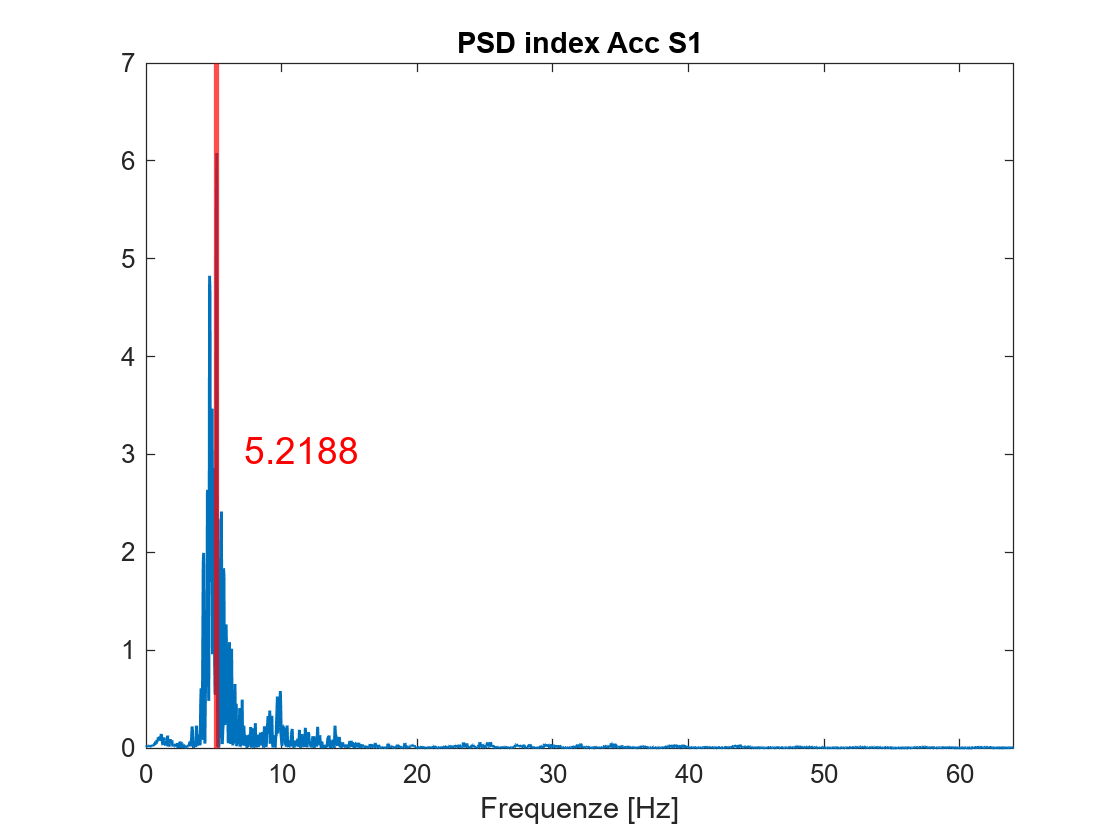

figure()
plot(f_acc, psd_acc,'LineWidth',1.2)
title('PSD index Acc S1')
hold on
xline(f_dominant_dito_acc_1,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_acc(end)])
text(f_dominant_dito_acc_1 + 2, max(psd_acc)/2, num2str(f_dominant_dito_acc_1), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf, 'f_dominant_dito_acc_1.jpg', 'jpg');

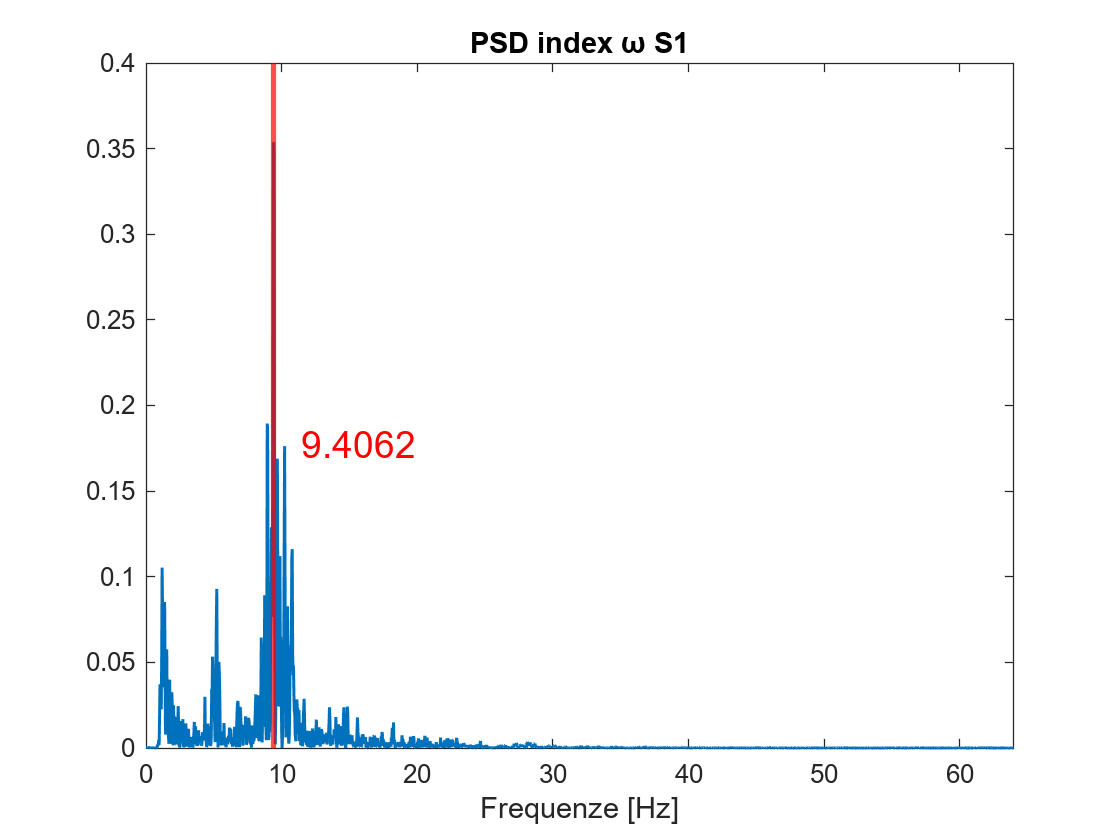


figure()
plot(f_v, psd_v,'LineWidth',1.2)
title('PSD index ω S1')
hold on
xline(f_dominant_dito_v_1,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_v(end)])
text(f_dominant_dito_v_1 + 2, max(psd_v)/2, num2str(f_dominant_dito_v_1), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf, 'f_dominant_dito_v_1.jpg', 'jpg');

**THUMB FINGER**

Time and sample frequency extraction.

p_tremor_pollice_tempo = dati.Subj{1}.off.taskAS315.pollice.t;
p_tremor_pollice_f_samp = dati.Subj{1}.off.taskAS315.pollice.fs;

ButterWorth 4th order High-Pass filter (cut-off frequency: 1 Hz).

order = 4;  
low_freq = 1;  
 
nyquist = 0.5 * p_tremor_pollice_f_samp;
low_freq_normalized = low_freq / nyquist;
[b, a] = butter(order, low_freq_normalized, 'high');

Data extraction.

for i=1:3
    p_tremor_pollice_acc(:,i) = dati.Subj{1}.off.taskAS315.pollice.acc(:,i);
    p_tremor_pollice_v(:,i) = dati.Subj{1}.off.taskAS315.pollice.gyro(:,i);   
end

Acceleration and Angular Velocity modules.

p_tremor_pollice_vec_acc(:) = sqrt(p_tremor_pollice_acc(:,1).^2+p_tremor_pollice_acc(:,2).^2+p_tremor_pollice_acc(:,3).^2);
p_tremor_pollice_vec_v(:) = sqrt(p_tremor_pollice_v(:,1).^2+p_tremor_pollice_v(:,2).^2+p_tremor_pollice_v(:,3).^2);

Filter application.

p_tremor_pollice_filt_vec_acc = filtfilt(b,a,p_tremor_pollice_vec_acc);
p_tremor_pollice_filt_vec_v = filtfilt(b,a,p_tremor_pollice_vec_v);

Computation of PSD (Acceleration). 

[psd_acc, f_acc] = periodogram(p_tremor_pollice_filt_vec_acc,[], [], p_tremor_pollice_f_samp);

The dominant frequency is the one corresponding to the maximum of the PSD (Acceleration).

[value index] = max(psd_acc);
f_dominant_pollice_acc_1 = f_acc(index)

f_dominant_pollice_acc_1 = 5.3750

save("f_dominant_pollice_acc_1","f_dominant_pollice_acc_1")

Computation of PSD (Angular Velocity). 

[psd_v, f_v] = periodogram(p_tremor_pollice_filt_vec_v, [],[], p_tremor_pollice_f_samp);

The dominant frequency is the one corresponding to the maximum of the PSD (Angular Velocity).

[value index] = max(psd_v);
f_dominant_pollice_v_1 = f_v(index)

f_dominant_pollice_v_1 = 9.8125

save("f_dominant_pollice_v_1","f_dominant_pollice_v_1")

Plots.

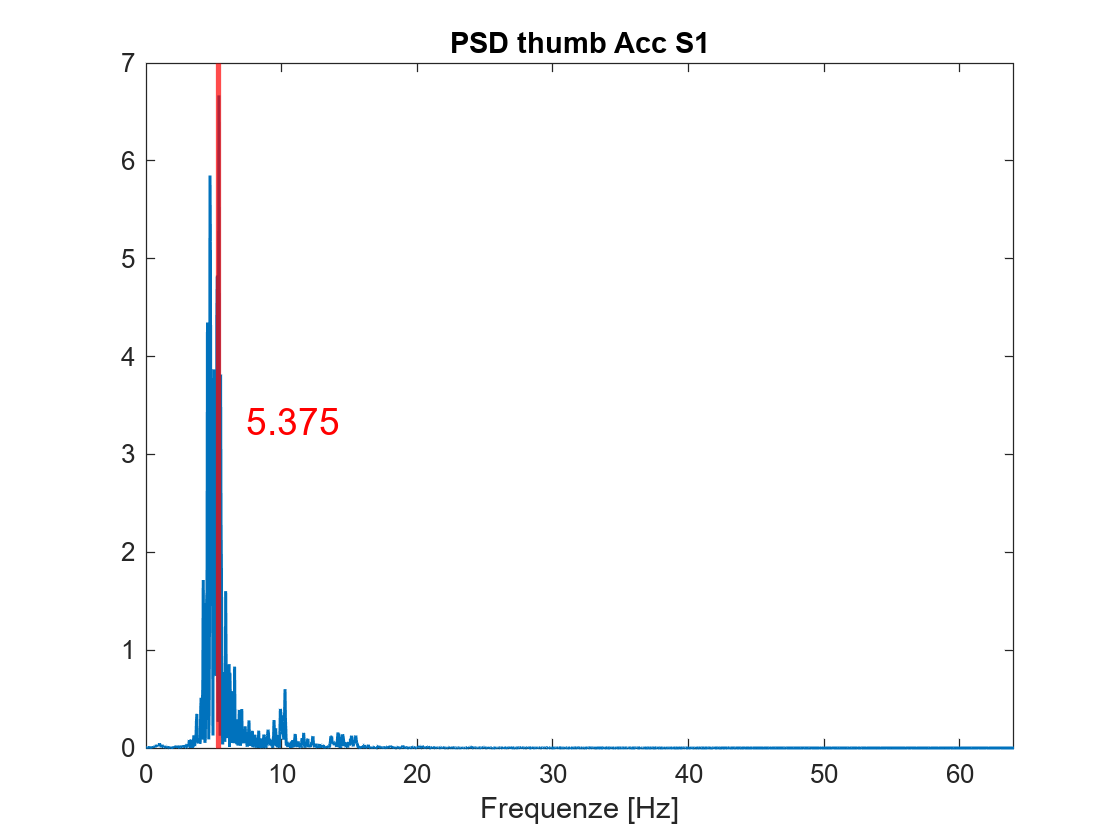

figure()
plot(f_acc, psd_acc,'LineWidth',1.2)
title('PSD thumb Acc S1')
hold on
xline(f_dominant_pollice_acc_1,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_acc(end)])
text(f_dominant_pollice_acc_1 + 2, max(psd_acc)/2, num2str(f_dominant_pollice_acc_1), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf, 'f_dominant_pollice_acc_1.jpg', 'jpg');

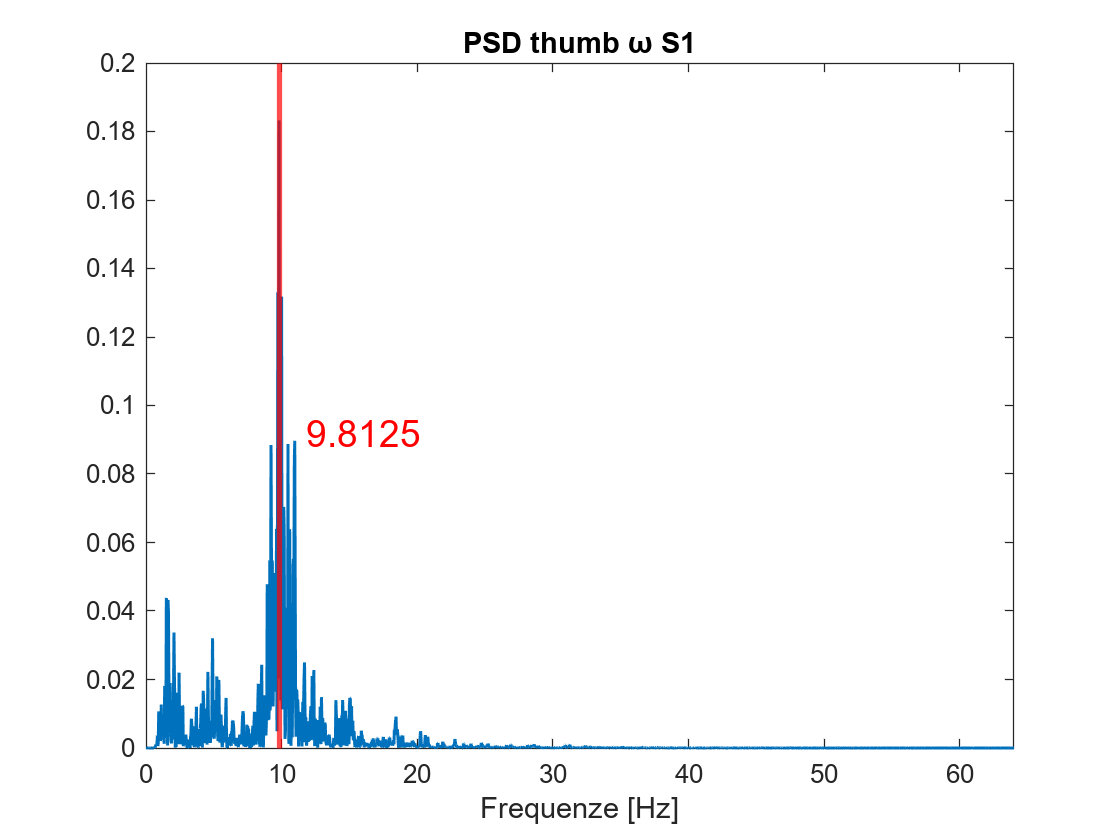


figure()
plot(f_v, psd_v,'LineWidth',1.2)
title('PSD thumb ω S1')
hold on
xline(f_dominant_pollice_v_1,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_v(end)])
text(f_dominant_pollice_v_1 + 2, max(psd_v)/2, num2str(f_dominant_pollice_v_1), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf, 'f_dominant_pollice_v_1.jpg', 'jpg');

**METACARPAL**

Time and sample frequency extraction.

p_tremor_metacarpo_tempo = dati.Subj{1}.off.taskAS315.metacarpo.t;
p_tremor_metacarpo_f_samp = dati.Subj{1}.off.taskAS315.metacarpo.fs;

ButterWorth 4th order High-Pass filter (cut-off frequency: 1 Hz).

order = 4;  
low_freq = 1;  
 
nyquist = 0.5 * p_tremor_metacarpo_f_samp;
low_freq_normalized = low_freq / nyquist;
[b, a] = butter(order, low_freq_normalized, 'high');

Data extraction.

for i=1:3
    p_tremor_metacarpo_acc(:,i) = dati.Subj{1}.off.taskAS315.metacarpo.acc(:,i);
    p_tremor_metacarpo_v(:,i) = dati.Subj{1}.off.taskAS315.metacarpo.gyro(:,i);   
end

Acceleration and Angular Velocity modules.

p_tremor_metacarpo_vec_acc(:) = sqrt(p_tremor_metacarpo_acc(:,1).^2+p_tremor_metacarpo_acc(:,2).^2+p_tremor_metacarpo_acc(:,3).^2);
p_tremor_metacarpo_vec_v(:) = sqrt(p_tremor_metacarpo_v(:,1).^2+p_tremor_metacarpo_v(:,2).^2+p_tremor_metacarpo_v(:,3).^2);

Filter application.

p_tremor_metacarpo_filt_vec_acc = filtfilt(b,a,p_tremor_metacarpo_vec_acc);
p_tremor_metacarpo_filt_vec_v = filtfilt(b,a,p_tremor_metacarpo_vec_v);

Computation of PSD (Acceleration).

[psd_acc, f_acc] = periodogram(p_tremor_metacarpo_filt_vec_acc,[], [], p_tremor_metacarpo_f_samp);

The dominant frequency is the one corresponding to the maximum of the PSD (Acceleration).

[value index] = max(psd_acc);
f_dominant_metacarpo_acc_1 = f_acc(index)

f_dominant_metacarpo_acc_1 = 5.2188

save("f_dominant_metacarpo_acc_1","f_dominant_metacarpo_acc_1")

Computation of PSD (Angular Velocity). 

[psd_v, f_v] = periodogram(p_tremor_metacarpo_filt_vec_v, [],[], p_tremor_metacarpo_f_samp);

The dominant frequency is the one corresponding to the maximum of the PSD (Angular Velocity).

[value index] = max(psd_v);
f_dominant_metacarpo_v_1 = f_v(index)

f_dominant_metacarpo_v_1 = 9.9063

save("f_dominant_metacarpo_v_1","f_dominant_metacarpo_v_1")

Plots.

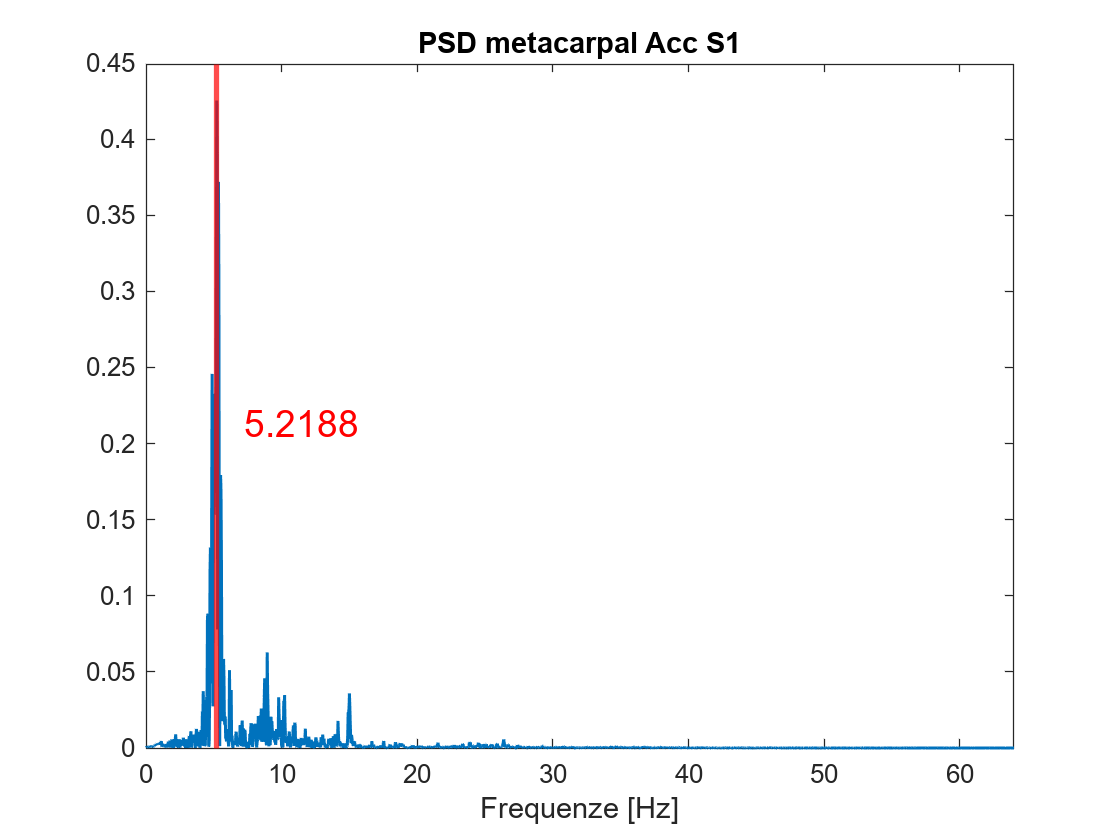

figure()
plot(f_acc, psd_acc,'LineWidth',1.2)
title('PSD metacarpal Acc S1')
hold on
xline(f_dominant_metacarpo_acc_1,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_acc(end)])
text(f_dominant_metacarpo_acc_1 + 2, max(psd_acc)/2, num2str(f_dominant_metacarpo_acc_1), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf, 'f_dominant_metacarpo_acc_1.jpg', 'jpg');

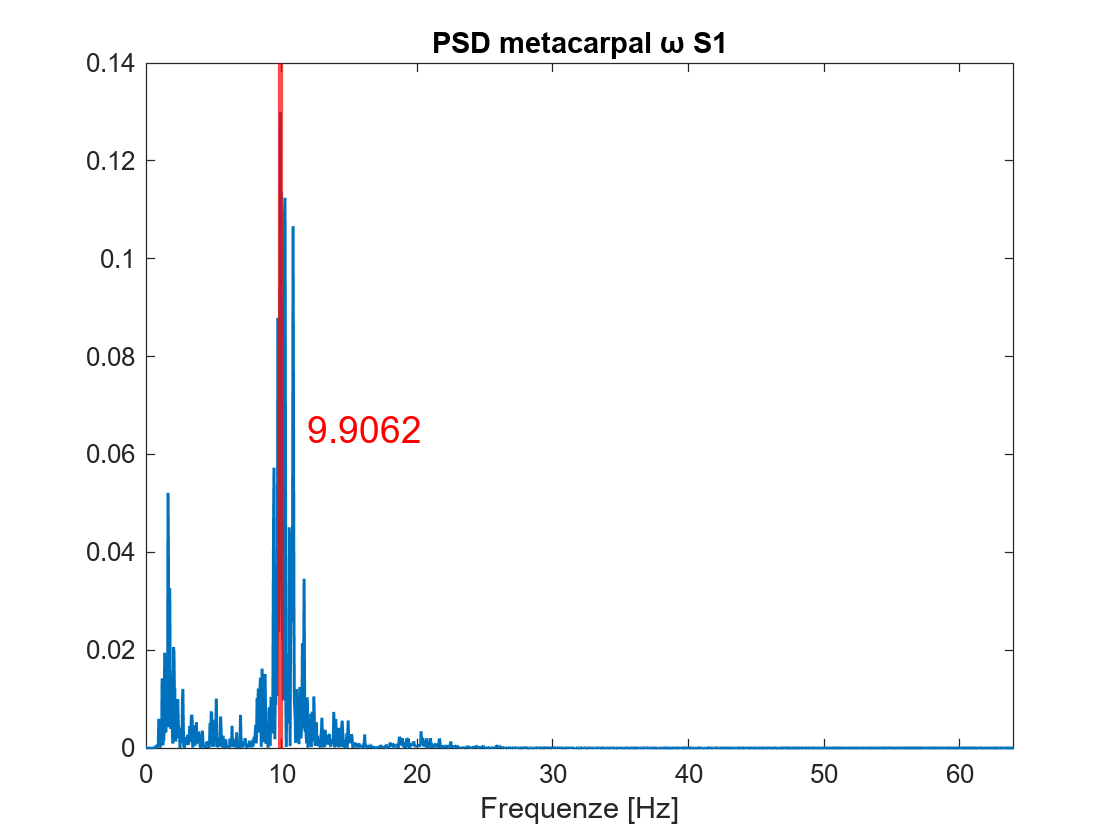


figure()
plot(f_v, psd_v,'LineWidth',1.2)
title('PSD metacarpal ω S1')
hold on
xline(f_dominant_metacarpo_v_1,'r', 'LineWidth',2)
xlabel('Frequenze [Hz]')
xlim([0 f_v(end)])
text(f_dominant_metacarpo_v_1 + 2, max(psd_v)/2, num2str(f_dominant_metacarpo_v_1), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color','r', 'FontSize',14);
saveas(gcf, 'f_dominant_metacarpo_v_1.jpg', 'jpg');